# Fit for AP1903 and BLAST data together:

## Full System*:


$$R_{growth}=  (\psi_g + \psi_d)\cdot\frac{(\eta_AA + 1)^4 + \left(\frac{P_R}{\delta}\right)^4}{(\eta_B B_{ext} + 1)(\eta_AA+ 1)^4+ \left( \frac{P_R}{\delta} \right)^4 } - \psi_d-\psi_C \cdot \frac{\eta_{I} I \cdot  \left(\frac{P_C}{\delta}\right)^2}{\eta_{I}I \cdot \left(\frac{P_C}{\delta}\right)^2+(\eta_AA +1)^2} $$



$$\frac{\mathrm{dy}}{\mathrm{dt}}=R_{\mathrm{growth}\;} \cdot y\left(1-y\right)$$


*Note that ydata is the ratio of cell number to confluent cell number 

Input the observation axuin levels:

clear all; close all
addpath('./MatlabFuncs/')

xdata = [ 0 .2 .5 1 2 5 10 20 50 100];

%%NoAP1903
ydata1 = [0.994351247	0.9916548	0.989389418	0.996206878	0.994587755	0.983118519...
 	  0.893697128	0.400989342	0.006447241	0.00148715];
%%NoBlast
ydata2 = [0.020884656	0.038708919	0.053608692	0.0795322	0.106651625	0.426742328...
 	  0.801811791	0.927911111	0.978334618	0.916049206];
%%BothAdded
ydata3 = [0.028152532	0.050824187	0.055106803	0.078311489	0.12464966	0.216782237...
 	  0.052270824	0.020610733	0.004709373	0.000569237];


% Converting y to growth rate
Y0 = 1/12; K = 1; t=96;
rdata = revLogest([ydata1; ydata2; ydata3], Y0, K, t);
disp(rdata);

    0.0788    0.0747    0.0722    0.0830    0.0793    0.0673    0.0472    0.0208   -0.0275   -0.0428
   -0.0151   -0.0085   -0.0049   -0.0005    0.0028    0.0219    0.0395    0.0516    0.0647    0.0499
   -0.0119   -0.0055   -0.0046   -0.0007    0.0047    0.0116   -0.0052   -0.0152   -0.0308   -0.0528



## Fit the data to the model. 

## AP1903 =0: 


$$log(\hbox{ydata}) - log\left(\frac{N_0}{N_{confluent}}\right) =  (\psi_g + \psi_d)\cdot\frac{(\eta_AA + 1)^4 + \left(\frac{P_R}{\delta}\right)^4}{(\eta_B B_{ext} + 1)(\eta_AA+ 1)^4+ \left( \frac{P_R}{\delta} \right)^4 } - \psi_d$$


## Blast =0:


$$log(\hbox{ydata}) - log\left(\frac{N_0}{N_{confluent}}\right) = \psi_g-\psi_C \frac{I^*\left(\frac{P_C}{\delta}\right)^2}{I^*\left(\frac{P_C}{\delta}\right)^2+(\eta_AA +1)^2}$$


  x(1) = $\psi_g =\delta$ (let vary for curiosity) , x(2) = $\eta_A$, x(3) = $\psi_C$, x(4) = $I^* P_C^2$, x(5) = $\psi_d$,  x(6) = $B^* =\eta_B B_{\textrm{ext}}$, x(7) = $P_R$ 

rate_both = @(x,xdata)([
    ((x(1) + x(5)) .* transReduc(x,xdata)) - x(5);
    x(1)- x(3) .* apopActi(x, xdata)
    ]);

options = optimoptions('lsqcurvefit','MaxFunctionEvaluations',100000, 'MaxIterations',40000); 
x0_both = [0.78, 1/0.76, .1, .1, 1, 5, 2];


[x_both, renorm_both, residual_both] = lsqcurvefit(rate_both,x0_both,xdata,[rdata(1, :); rdata(2, :)],[0 1/0.76 0 0 0 0 0],[inf 1/0.76 inf inf inf inf inf],options);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


MSE_both = mean((residual_both).^2,2); % mean percentage error
MPE_both = mean((residual_both)./ydata1,2).*100; % mean percentage error

disp(x_both)

    0.0755    1.3158    0.0825    0.9510    0.1711    4.1092   30.1780



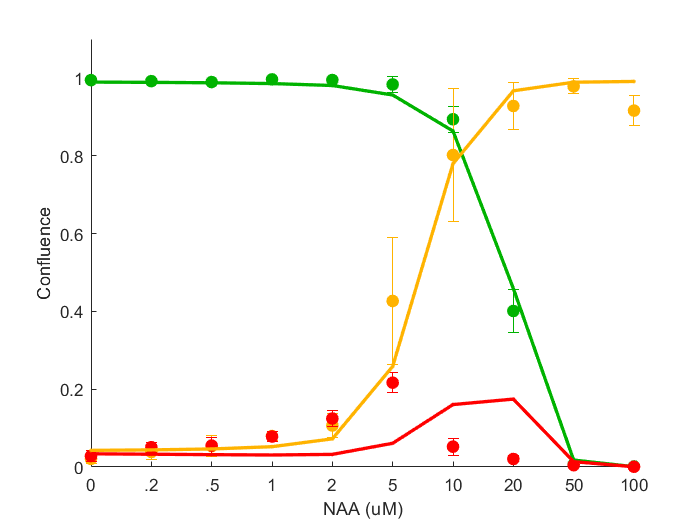

%%standard_dev
err1 = [0.002809344	0.005162316	0.004957646	0.001467934	0.002520465	0.019980023	0.033964324	0.054158992	0.002579971	0.000759584];
err2 = [0.010813322	0.018252794	0.026223576	0.012246634	0.031479622	0.16338727	0.171613373	0.059727441	0.01959887	0.03884396];
err3 = [0.014081056	0.012390267	0.020057457	0.012582435	0.020161014	0.025438707	0.021837773	0.007677594	0.004816866	0.00058251];


rpredict = rate_both(x_both, xdata);
cpredict = endLogest(rpredict, Y0, 1, t);

rpredict3 = growthRate(x_both, xdata);
cpredict3 = endLogest(rpredict3, Y0, 1, t);

fig = figure(1); clf(fig);

hold on

e1 = errorbar([1:length(xdata)],ydata1,err1,'o','Color',[0,.7,0],'MarkerSize',7,...
    'MarkerEdgeColor',[0,.7,0],'MarkerFaceColor',[0,.7,0]);
e2 = errorbar([1:length(xdata)],ydata2,err2,'o','Color',[1,.7,0],'MarkerSize',7,...
    'MarkerEdgeColor',[1,.7,0],'MarkerFaceColor',[1,.7,0]);
e3 = errorbar([1:length(xdata)],ydata3,err3,'o','Color',[1,0,0],'MarkerSize',7,...
    'MarkerEdgeColor',[1,0,0],'MarkerFaceColor',[1,0,0]);

p1 = plot([1:length(xdata)],cpredict(1,:),'.-','Color',[0,.7,0],'MarkerFaceColor',[0,.7,0],'LineWidth',2);
p2 = plot([1:length(xdata)],cpredict(2,:),'.-','Color',[1,.7,0],'MarkerFaceColor',[1,.7,0],'LineWidth',2);
p3 = plot([1:length(xdata)],cpredict3,'.-','Color',[1,0,0],'MarkerFaceColor',[1,0,0],'LineWidth',2);

ylim([0, 1.1])
xticklabels({'0','.2','.5','1','2','5','10', '20', '50', '100'});
xlabel('NAA (uM)');
ylabel({'Confluence'});
gca.FontSize = 24;

box off;